clear;clc;

origState = rng(17);
msg = randi([0 1],800,1);
%Generate complex signals
cfg4a = lrwpanHRPConfig( ...
    Mode='802.15.4a', ...
    MeanPRF=15.6, ...
    Channel=3, ...
    CodeIndex=6, ...
    PSDULength=length(msg)/8) %#ok<NOPTS>

cfg4a =   lrwpanHRPConfig - 属性:

             Channel: 3
                Mode: '802.15.4a'
             MeanPRF: 15.6000
            DataRate: 0.8500
     SamplesPerPulse: 4
           CodeIndex: 6
     PreambleMeanPRF: 16.1000
    PreambleDuration: 64
             Ranging: 0
          PSDULength: 100

   Read-only properties:
          SampleRate: 1.9968e+09


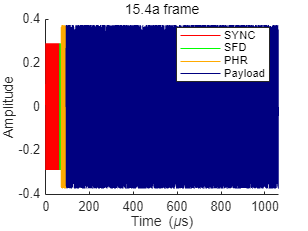

wave4a = lrwpanWaveformGenerator(msg,cfg4a);
%Note: It is a baseband signal.
lrwpanPlotFrame(wave4a,cfg4a);

%HPRF has configuration of samplesPerPulse

info(cfg4a ...
    )

ans = 包含以下字段的 struct :
                    PeakPRF: 499.2000
            BurstsPerSymbol: 32
               NumHopBursts: 8
              ChipsPerBurst: 16
             ChipsPerSymbol: 512
        ConvolutionalCoding: 1
         PreambleCodeLength: 31
    PreambleSpreadingFactor: 16



indices = lrwpanHRPFieldIndices(cfg4a); % length (start/end) of each field
preamble = wave4a( ...
    1:indices.SYNC(end)/cfg4a.PreambleDuration); % 1 of the Nsync repetitions
% plot(preamble)


%这是调制后的载波
channelSpec = [3 4992.8e6 499.2e6];
channelNum = channelSpec(1);
Fc = channelSpec(2);
bw = channelSpec(3);
fprintf('Channel #%d: Center frequency = %.1f MHz, Bandwidth = %.1f MHz.\n', channelNum, Fc/1e6, bw/1e6);

Channel #3: Center frequency = 4992.8 MHz, Bandwidth = 499.2 MHz.


% 旋转函数
function rotated_points = rotate_points(points, angle, center)
    theta = deg2rad(angle);
    rotation_matrix = [cos(theta), -sin(theta); sin(theta), cos(theta)];
    rotated_points = (rotation_matrix * (points' - center') + center')';
end

function [peaksChosen,peaksChosenValue]=findMPC(cir)
    [peaksValue,peaksIdx]=findpeaks(cir);
    %设置阈值
    threshold=0.3*max(abs(cir));
    %找到所有在阈值之上的峰，需要记录峰的索引和峰值
    peaksChosen=peaksIdx(peaksValue>threshold);
    peaksChosenValue=peaksValue(peaksValue>threshold);
end


function cross_corr=CalculateXCorr(preamble,signal)
    % 计算信号的长度
    len1 = length(preamble);
    len2 = length(signal);
    
    % 扩展信号1和信号2，使其长度相等
    maxLen = max(len1, len2);
    signal1 = [preamble; zeros(maxLen - len1,1)];
    signal2 = [signal; zeros(maxLen - len2,1)];
    
    % 对信号1取复共轭
    signal1=flipud(signal1);
    signal2_conj = conj(signal2);
    
    % 计算互相关操作
    cross_corr = ifft(fft(signal2_conj) .* fft(signal1));
end


function adjusted_array = adjust_to_range(array)
    adjusted_array = array;
    for i = 1:numel(array)
        while adjusted_array(i) > pi
            adjusted_array(i) = adjusted_array(i) - 2*pi;
        end
        while adjusted_array(i) < -pi
            adjusted_array(i) = adjusted_array(i) + 2*pi;
        end
    end
end


%peaksPhase为某个TX发射，NRX个接收天线接收的相位
function AOA=CalculateAOA(peaksPhase,tx_array_length,rx_array_length,antennaSpacing,frequency)
    % 初始化一个 cell 数组用于存储分割后的子矩阵
    tx_matrices = cell(1, tx_array_length);
    % 使用循环分割矩阵
    for i = 1:tx_array_length
        % 提取当前子矩阵并存储到 cell 数组中
        tx_matrices{i} = peaksPhase(i:tx_array_length:length(peaksPhase),:);
    end
    AOA=[];
    for i=1:tx_array_length            
            peaksPhases=angle(tx_matrices{i});
            phaseDifferences=diff(peaksPhases);
            phaseDifferences=adjust_to_range(phaseDifferences);
            phaseSum=sum(phaseDifferences,1);
            % 计算相位差对应的到达角度（以弧度为单位）
            c=physconst('Lightspeed');
            theta_radians = asin(phaseDifferences * c / (2 * pi * antennaSpacing * frequency));
            theta_radians2 = asin(phaseSum* c / (2 * pi * 2 * antennaSpacing * frequency));
            % 将弧度转换为度数
            theta_degrees = rad2deg(theta_radians);
            theta_degrees2 = rad2deg(theta_radians2);
            theta_degrees=[theta_degrees;theta_degrees2];
            AOA=[AOA;mean(theta_degrees)];
    end
end



%peaksPhase为NTX发射，某一接收天线收到的NTX个相位
function AOD=CalculateAOD(peaksPhase,tx_array_length,rx_array_length,antennaSpacing,frequency)
    % 初始化一个 cell 数组用于存储分割后的子矩阵
    rx_matrices = cell(1, rx_array_length);
    % 使用循环分割矩阵
    for i = 1:tx_array_length
        start_row = (i - 1) * rx_array_length + 1;
        end_row = i * rx_array_length;
        % 提取当前子矩阵并存储到 cell 数组中
        rx_matrices{i} = peaksPhase(start_row:end_row, :);
    end
    AOD=[];
    for i = 1:rx_array_length
        peaksPhases=angle(rx_matrices{i});
        phaseDifferences=diff(peaksPhases);
        phaseDifferences=adjust_to_range(phaseDifferences);
        phaseSum=sum(phaseDifferences,1);
        % 计算相位差对应的到达角度（以弧度为单位）
        c=physconst('Lightspeed');
        theta_radians = asin(phaseDifferences * c / (2 * pi * antennaSpacing * frequency));
        theta_radians2 = asin(phaseSum* c / (2 * pi * 2 * antennaSpacing * frequency));
        % 将弧度转换为度数
        theta_degrees = rad2deg(theta_radians);
        theta_degrees2 = rad2deg(theta_radians2);
        theta_degrees=[theta_degrees;theta_degrees2];
        AOD=[AOD;mean(theta_degrees)];
    end
end


function x0 = findLocalization(theta1, theta2, phi1, phi2, rTOF)
    theta1 = deg2rad(theta1);
    theta2 = deg2rad(theta2);
    phi1 = deg2rad(phi1);
    phi2 = deg2rad(phi2);

    % 定义网格大小和范围
    gridRange = 20;
    gridSize = 0.5;

    % 生成网格点坐标
    [x1, y1, x2, y2] = ndgrid(-gridRange:gridSize:gridRange, -gridRange:gridSize:gridRange, -gridRange:gridSize:gridRange, -gridRange:gridSize:gridRange);
    x0 = [x1(:), y1(:), x2(:), y2(:)];

    % 计算目标函数值
    objectiveValues = objectiveFunction(x0, theta1, theta2, phi1, phi2, rTOF);

    % 找到最小值
    [~, idx] = min(objectiveValues);
    x0 = x0(idx, :);
end

function fval = objectiveFunction(x, theta1, theta2, phi1, phi2, rTOF)
    x1 = x(:, 1);
    y1 = x(:, 2);
    x2 = x(:, 3);
    y2 = x(:, 4);

    % 计算目标函数值
    fval = (tan(theta1) - x1./y1).^2 + (tan(theta2) - x2./y2).^2 + (tan(phi1 + theta1 - phi2) - (x1 - x2)./(y1 - y2)).^2 + ((rTOF * physconst('Lightspeed') * 1e-9) - (-sqrt(x1.^2 + y1.^2) + sqrt(x2.^2 + y2.^2) + sqrt((x1 - x2).^2 + (y1 - y2).^2))).^2;
end

% 定义接收位置和对应的测量误差
errors=[];
TXs=[];

% 定义墙面特性
wall1_position = [3, 0]; % 墙面1位置
wall2_position = [1, 5]; % 墙面2位置
reflection_coefficient = 0.8; % 反射系数

% 定义天线特性
tx_antenna_gain = 2; % 发射天线增益为 2 dB
rx_antenna_gain = 2; % 接收天线增益为 2 dB

% 配置天线阵列
tx_array_length = 3;
rx_array_length = 3;
c =physconst("LightSpeed"); % wavelength (assume)
lambda=c/4992.8e6;
antennaSpacing = lambda / 2;
tx_array_spacing = antennaSpacing;
rx_array_spacing = antennaSpacing;
tx_array_angle = 135; % 发射端天线阵列与水平轴夹角
rx_array_angle = 135; % 接收端天线阵列与水平轴夹角

% 定义天线位置
rx_position = [0, 0]; 

%UWB的频率和采样率
frequency=4992.8e6;
fs=cfg4a.SampleRate;

%遍历tag的位置
% tx_position = [15, 15]; 

for x=8:15
    for y=8:15
        tx_position=[x,y];
        rx_position=[0,0];
        % 计算天线阵列位置
        tx_array_positions = [tx_position-[tx_array_spacing,0];tx_position;tx_position+[tx_array_spacing,0]];
        rx_array_positions = [rx_position-[rx_array_spacing,0];rx_position;rx_position+[rx_array_spacing,0]];
        
        
        % 将天线阵列位置进行旋转
        tx_array_positions = rotate_points(tx_array_positions, tx_array_angle, tx_position);
        rx_array_positions = rotate_points(rx_array_positions, rx_array_angle, rx_position);
        

        
        % % 计算锚点到标签的向量
        % vecAnchorToTag = rx_position-tx_position;
        % 
        % 
        % 
        % 
        % % 计算锚点到标签的向量
        % vecAnchorToTag = rx_position - tx_position;
        % 
        % % 计算向量的长度
        % distAnchorToTag = norm(vecAnchorToTag);
        % 
        % % 计算向量与参考向量[-1/sqrt(2), -1/sqrt(2)]的夹角（以弧度为单位）
        % angleAnchorToTag = acos(dot(vecAnchorToTag, [-1/sqrt(2), -1/sqrt(2)]) / distAnchorToTag);
        % 
        % % 计算参考向量的叉乘以确定角度的正负值
        % cross_product = cross([-1/sqrt(2), -1/sqrt(2), 0], [vecAnchorToTag, 0]);
        
        % 如果参考向量在向量[-1/sqrt(2), -1/sqrt(2)]的上方，则夹角为负值，否则为正值
        % if cross_product(3) < 0
        %     angleAnchorToTag = -angleAnchorToTag;
        % end
        % 
        % % 将夹角转换为度数
        % angleAnchorToTag = rad2deg(angleAnchorToTag);        
        peaksPhase=[];
        timestamp=[];        
        for j=1:rx_array_length
            rx_position = rx_array_positions(j,:);
            for i=1:tx_array_length
                tx_position = tx_array_positions(i,:);
                direct_path_distance = norm(rx_position - tx_position); % 直射路径距离
                reflection1_distance = norm(wall1_position - tx_position) + norm(wall1_position - rx_position); % 墙面1反射路径距离
                reflection2_distance = norm(wall2_position - tx_position) + norm(wall2_position - rx_position); % 墙面2反射路径距离
                %TODO:Here is a problem about PL
                % % 计算传播损耗
                % % direct_path_loss_dB = 20*log10(direct_path_distance)  - 147.55; % dB
                % % reflection1_loss_dB = 20*log10(reflection1_distance)  - 147.55; % dB
                % % reflection2_loss_dB = 20*log10(reflection2_distance)  - 147.55; % dB
                % direct_path_loss_dB = 20*log10(direct_path_distance) +20*log10(4992.8e6) - 147.55; % dB
                % reflection1_loss_dB = 20*log10(reflection1_distance) +20*log10(4992.8e6)- 147.55; % dB
                % reflection2_loss_dB = 20*log10(reflection2_distance) +20*log10(4992.8e6)- 147.55; % dB
                % % % %转换分贝为功率比P_TX/P_RX
                % direct_path_loss_ratio = 10^(-direct_path_loss_dB / 20); % 将分贝值转换为功率比
                % reflection1_loss_ratio = 10^(-reflection1_loss_dB / 20); % 将分贝值转换为功率比
                % reflection2_loss_ratio = 10^(-reflection2_loss_dB / 20); % 将分贝值转换为功率比
                % % 将分贝增益转换为线性增益
                % tx_antenna_gain = 10^(tx_antenna_gain / 10);
                % rx_antenna_gain = 10^(rx_antenna_gain / 10);
                % % 接收信号与发射信号的幅度比
                received_signal_direct=wave4a * lambda / (4*pi*direct_path_distance);
                received_signal_reflection1=wave4a * reflection_coefficient * lambda / (4*pi*reflection1_distance);
                received_signal_reflection2=wave4a * reflection_coefficient * lambda / (4*pi*reflection2_distance);
                
                % 定义传播速度（假设与光速相同）
                speed_of_light = physconst("Lightspeed");
                
                % % 模拟传播过程
                % received_signal_direct = wave4a - direct_path_loss + tx_antenna_gain + rx_antenna_gain; % 直射路径
                % received_signal_reflection1 = wave4a * reflection_coefficient - reflection1_loss + tx_antenna_gain + rx_antenna_gain; % 墙面1反射路径
                % received_signal_reflection2 = wave4a* reflection_coefficient - reflection2_loss + tx_antenna_gain + rx_antenna_gain; % 墙面2反射路径
                
                % % % 设置更高的采样频率
                % fs = 10 * cfg4a.SampleRate; 
                % % % 得到各个path的多经时延信号，并进行upsampling
                % received_signal_direct = resample(received_signal_direct, fs, cfg4a.SampleRate);
                % received_signal_reflection1 = resample(received_signal_reflection1, fs, cfg4a.SampleRate);
                % received_signal_reflection2 = resample(received_signal_reflection2, fs, cfg4a.SampleRate);
                % preamble=resample(preamble,fs,cfg4a.SampleRate);
            
                % Calculate the phase shift for each path
                direct_path_phase_shift = exp(-1j * 2 * pi * direct_path_distance / lambda);
                reflection1_phase_shift = exp(-1j * 2 * pi * reflection1_distance / lambda);
                reflection2_phase_shift = exp(-1j * 2 * pi * reflection2_distance / lambda);
                
                % Apply phase shifts to received signals
                received_signal_direct_phase = received_signal_direct .* direct_path_phase_shift;
                received_signal_reflection1_phase = received_signal_reflection1 .* reflection1_phase_shift;
                received_signal_reflection2_phase = received_signal_reflection2 .* reflection2_phase_shift;
        
                % 计算传播时延
                direct_path_delay = direct_path_distance / speed_of_light; % 直射路径时延（秒）
                reflection1_delay = reflection1_distance / speed_of_light; % 反射路径1时延（秒）
                reflection2_delay = reflection2_distance / speed_of_light; % 反射路径2时延（秒）
                
                %得到各个path的多经时延信号
                received_signal_direct_delayed = [zeros(round(direct_path_delay * fs),1) ;received_signal_direct_phase];
                received_signal_reflection1_delayed = [zeros(round(reflection1_delay * fs),1) ;received_signal_reflection1_phase];
                received_signal_reflection2_delayed = [zeros(round(reflection2_delay * fs),1); received_signal_reflection2_phase];
            
                len1 = length(received_signal_direct_delayed);
                len2 = length(received_signal_reflection1_delayed);
                len3 = length(received_signal_reflection2_delayed);
                maxLen = max(len1,len2);
                maxLen =max(maxLen,len3);
                received_signal_direct_delayed = [received_signal_direct_delayed; zeros(maxLen - len1,1)];
                received_signal_reflection1_delayed = [received_signal_reflection1_delayed; zeros(maxLen - len2,1)];
                received_signal_reflection2_delayed=[received_signal_reflection2_delayed; zeros(maxLen - len3,1)];
            
            
                % 组合多径时延后的信号
                received_signal_total = received_signal_direct_delayed + ...
                    received_signal_reflection1_delayed + received_signal_reflection2_delayed;
                
                % 添加噪声
                noise_power = -80; % 噪声功率为 -80 dBm
                noise = awgn(zeros(size(received_signal_total)), noise_power, 'measured'); % 生成高斯白噪声
                
                %最终信号
                received_signal = received_signal_total+noise;
                receivedCorrelation=CalculateXCorr(preamble,received_signal);
                abs_correlation=abs(receivedCorrelation);
                reshaped_correlation = reshape(abs_correlation(1:indices.SYNC(end)), [], cfg4a.PreambleDuration);
                % 对每列求平均
                average_correlation = mean(reshaped_correlation, 2);
                % figure;
                % plot(average_correlation);
                % % 计算持续时间
                % numSamples = length(average_correlation); % 样本数
                % t = (0:numSamples-1)*1e9 / fs;
                % figure;
                % plot(t,average_correlation/max(average_correlation));
                % xlabel('ns');
                % ylabel('amplitude');
            
                [peaksChosen,peaksChosenValue]=findMPC(average_correlation);
                phases=receivedCorrelation(peaksChosen);
                if length(phases)>=2
                    peaksPhase=[peaksPhase;phases(1:2)'];
                    timestamp=[timestamp;peaksChosen(1:2)'*1e9 / fs];
                end
                % peaksPhase{3*(j-1)+i}=[peaksPhase{3*(j-1)+i};phases(1:end)'];
                % timestamp{3*(j-1)+i}=[timestamp{3*(j-1)+i};peaksChosen'*1e9 / fs];
                % % 绘制结果
                % t_delayed = (0:length(received_signal)-1) / fs; % 延迟后的时间向量
                % figure;
                % plot(t_delayed,received_signal);
                % xlabel('时间 (s)');
                % ylabel('信号幅度');
                % title('UWB信号传播仿真');
            end
        end
        if length(peaksPhase)==tx_array_length*rx_array_length
            AOD=mean(CalculateAOD(peaksPhase,tx_array_length,rx_array_length, antennaSpacing,frequency));
            AOA=mean(CalculateAOA(peaksPhase,tx_array_length,rx_array_length, antennaSpacing,frequency));
            timestamp=mean(timestamp,1);
            rTOF=timestamp-timestamp(1);
            rDistance=rTOF*physconst('Lightspeed')*1e-9;
            x0=findLocalization(AOA(1),AOA(2),AOD(1),AOD(2),rTOF(2));
            % 顺时针旋转45°的旋转矩阵
            x0=reshape(x0,2,2);
            x0(2,:)=-x0(2,:);
            theta = deg2rad(45);
            R = [cos(theta), sin(theta); -sin(theta), cos(theta)];        
            % 旋转后的向量
            result = R * x0(:,1);
        else 
            result=[inf,inf];
        end
            % 显示结果
        disp("TX:");
        disp([x,y])
        disp("Result:")
        disp(result);
        disp("Error:")
        error=sqrt((result(1)-x)^2+(result(2)-y)^2);
        disp(error);
        TXs=[TXs;[x,y]];
        errors=[errors;error];
        
        end 
end

TX:


     8     8



Result:


   13.4350
   14.8492



Error:


    8.7437



TX:


     8     9



Result:


    6.0104
    6.7175



Error:


    3.0279



TX:


     8    10



Result:


   13.0815
   15.2028



Error:


    7.2726



TX:


     8    11



Result:


   13.0815
   15.2028



Error:


    6.5943



TX:


     8    12



Result:


   10.9602
   17.3241



Error:


    6.0917



TX:


     8    13



Result:


  -10.6066
  -16.9706



Error:


   35.2766



TX:


     8    14



Result:


   12.0208
   16.2635



Error:


    4.6141



TX:


     8    15



Result:


    3.5355
    9.8995



Error:


    6.7784



TX:


     9     8



Result:


   11.6673
   10.2530



Error:


    3.4915



TX:


     9     9



Result:


   Inf   Inf



Error:


   Inf



TX:


     9    10



Result:


   Inf   Inf



Error:


   Inf



TX:


     9    11



Result:


   12.0208
   16.2635



Error:


    6.0687



TX:


     9    12



Result:


   12.3744
   15.9099



Error:


    5.1647



TX:


     9    13



Result:


   12.7279
   15.5563



Error:


    4.5202



TX:


     9    14



Result:


   12.3744
   15.2028



Error:


    3.5823



TX:


     9    15



Result:


    4.5962
   10.9602



Error:


    5.9761



TX:


    10     8



Result:


   12.0208
    9.1924



Error:


    2.3464



TX:


    10     9



Result:


   14.1421
   13.4350



Error:


    6.0685



TX:


    10    10



Result:


   Inf   Inf



Error:


   Inf



TX:


    10    11



Result:


   12.0208
   16.2635



Error:


    5.6381



TX:


    10    12



Result:


    8.8388
   10.9602



Error:


    1.5587



TX:


    10    13



Result:


   11.6673
   16.6170



Error:


    3.9828



TX:


    10    14



Result:


   10.6066
   16.2635



Error:


    2.3433



TX:


    10    15



Result:


   10.2530
   17.3241



Error:


    2.3379



TX:


    11     8



Result:


   14.8492
   13.4350



Error:


    6.6600



TX:


    11     9



Result:


   15.9099
   10.9602



Error:


    5.2867



TX:


    11    10



Result:


   15.2028
   13.0815



Error:


    5.2114



TX:


    11    11



Result:


   10.6066
   13.4350



Error:


    2.4666



TX:


    11    12



Result:


   Inf   Inf



Error:


   Inf



TX:


    11    13



Result:


    9.5459
   12.3744



Error:


    1.5829



TX:


    11    14



Result:


    9.8995
   16.2635



Error:


    2.5168



TX:


    11    15



Result:


   11.6673
   16.6170



Error:


    1.7493



TX:


    12     8



Result:


   17.6777
   10.6066



Error:


    6.2474



TX:


    12     9



Result:


   15.9099
   12.3744



Error:


    5.1647



TX:


    12    10



Result:


   12.0208
   11.3137



Error:


    1.3139



TX:


    12    11



Result:


   15.5563
   12.7279



Error:


    3.9539



TX:


    12    12



Result:


   Inf   Inf



Error:


   Inf



TX:


    12    13



Result:


   11.3137
   11.3137



Error:


    1.8206



TX:


    12    14



Result:


   12.3744
   15.9099



Error:


    1.9462



TX:


    12    15



Result:


   12.0208
   15.5563



Error:


    0.5567



TX:


    13     8



Result:


   13.0815
    6.0104



Error:


    1.9913



TX:


    13     9



Result:


  -15.5563
  -11.3137



Error:


   35.0444



TX:


    13    10



Result:


   16.6170
   11.6673



Error:


    3.9828



TX:


    13    11



Result:


   15.2028
   13.0815



Error:


    3.0307



TX:


    13    12



Result:


   14.4957
   13.7886



Error:


    2.3315



TX:


    13    13



Result:


   Inf   Inf



Error:


   Inf



TX:


    13    14



Result:


   Inf   Inf



Error:


   Inf



TX:


    13    15



Result:


   11.6673
   14.4957



Error:


    1.4250



TX:


    14     8



Result:


  -19.7990
   -8.4853



Error:


   37.6050



TX:


    14     9



Result:


   16.9706
   11.3137



Error:


    3.7653



TX:


    14    10



Result:


   15.9099
   12.3744



Error:


    3.0472



TX:


    14    11



Result:


   16.2635
   12.0208



Error:


    2.4830



TX:


    14    12



Result:


   15.2028
   12.3744



Error:


    1.2597



TX:


    14    13



Result:


   14.8492
   13.4350



Error:


    0.9542



TX:


    14    14



Result:


   13.0815
   15.2028



Error:


    1.5134



TX:


    14    15



Result:


   Inf   Inf



Error:


   Inf



TX:


    15     8



Result:


   12.3744
    6.0104



Error:


    3.2943



TX:


    15     9



Result:


   18.0312
   10.2530



Error:


    3.2800



TX:


    15    10



Result:


   15.5563
   11.3137



Error:


    1.4267



TX:


    15    11



Result:


   17.3241
   10.9602



Error:


    2.3245



TX:


    15    12



Result:


   15.5563
   10.6066



Error:


    1.5004



TX:


    15    13



Result:


   14.8492
   12.7279



Error:


    0.3111



TX:


    15    14



Result:


   14.1421
   14.1421



Error:


    0.8696



TX:


    15    15



Result:


   15.5563
   12.0208



Error:


    3.0307



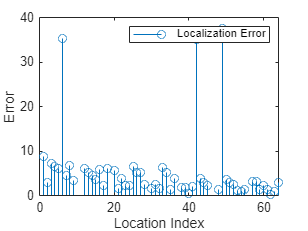

% figure;
% plot([errors,mean(errors,2)]);
% xlabel('Location Index');
% ylabel('Error');
% legend("AOD Error 1","AOD Error 2","AOD Error 3","Mean AOD Error");

figure;
stem(errors);
xlabel('Location Index');
ylabel('Error');
legend("Localization Error");